# Generate a spectral scene from an RGB image

ISETCam has methods to create spectral scenes from RGB file. 

The basic idea implemented in ISETCam is this:  We read the RGB image from the file, and we then assume the RGB data are shown on a specific calibrated display. This will produce spectral radiance from the display.  We use those spectral radiances to defeine the scene.  We assume that the illuminant is the display white point.

This produces an accurate result if we are really using a display.  But we may want to produce a scene that has more natural illuminant and reflectances.  To achieve that, we adjust the scene illuminant to a natural illuminant, such as D65.  

Finally, we have developed a method to read in the RGB image and produce a scene under a D65 illuminant with all of the reflectances within the 3D linear model of natural reflectances.  That is accomplished by using a special 'reflectance-display' that we created.  To see that logic, have a look at **s_displaySurfaceReflectance.**

## Initialize - image file and example displays

ieInit;

imgFileName = 'macbeth.tif';

dispOLEDFile = 'OLED-Sony.mat';
dispLCDFile = 'LCD-Apple.mat';
dispCRTFile = 'CRT-Dell.mat';

## Create a scene from a file assuming an OLED display

The illuminant is set to be the white point of the monitor.  In this format, the surface reflectances are not typical.

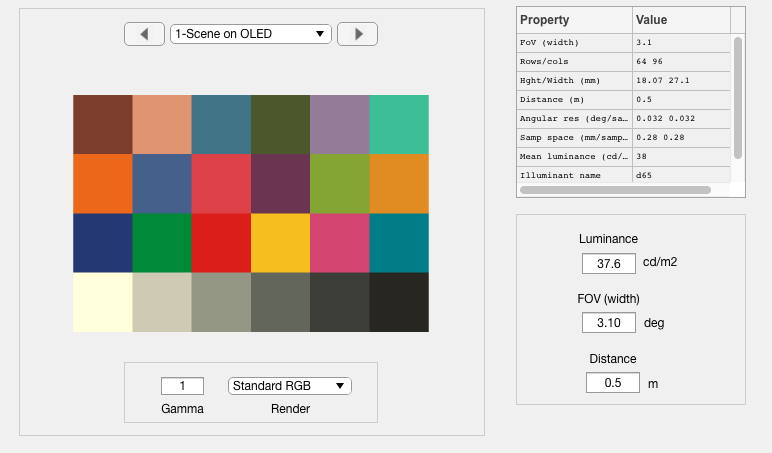

sceneA = sceneFromFile(imgFileName,'rgb',[],dispOLEDFile);
sceneA = sceneSet(sceneA,'name','Scene on OLED');
ieAddObject(sceneA); sceneWindow;

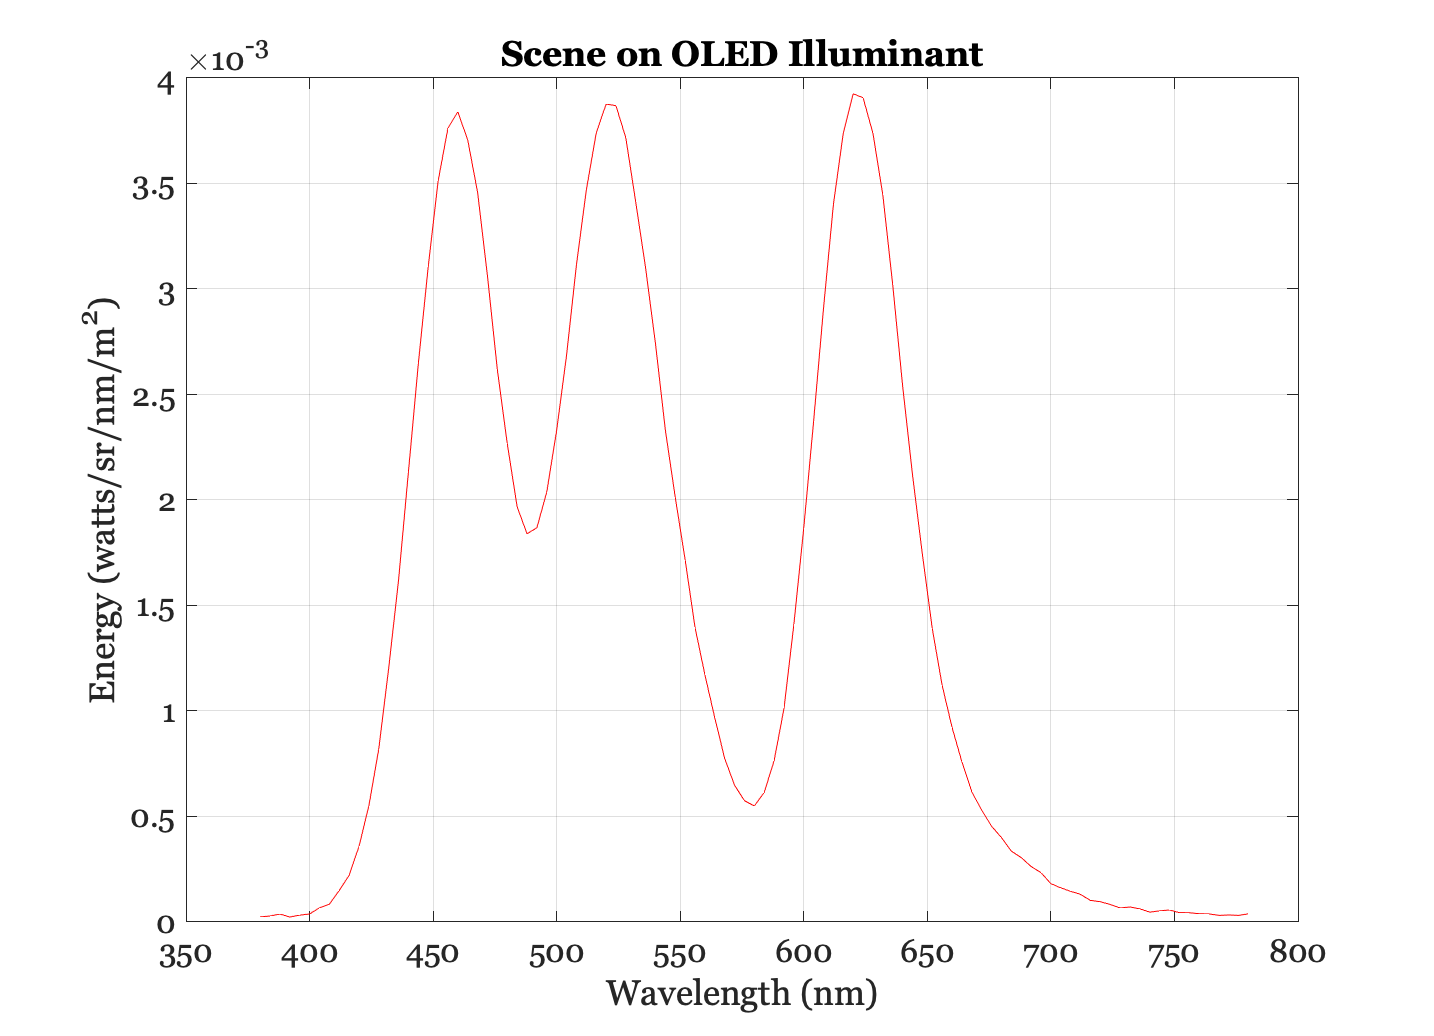

scenePlot(sceneA,'illuminant energy');

## Adjust the illuminant

The scene is rendered with an illuminant equal to the white point of the display.  This is not a natural illuminant, and we can adjust the illuminant to a more natural one this way. 

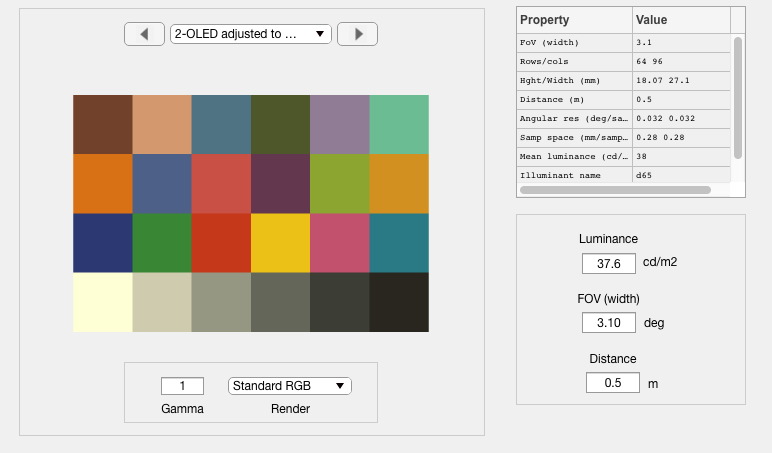

sceneA = sceneAdjustIlluminant(sceneA,'D65.mat');
sceneA = sceneSet(sceneA,'name','OLED adjusted to D65');
ieAddObject(sceneA); sceneWindow;

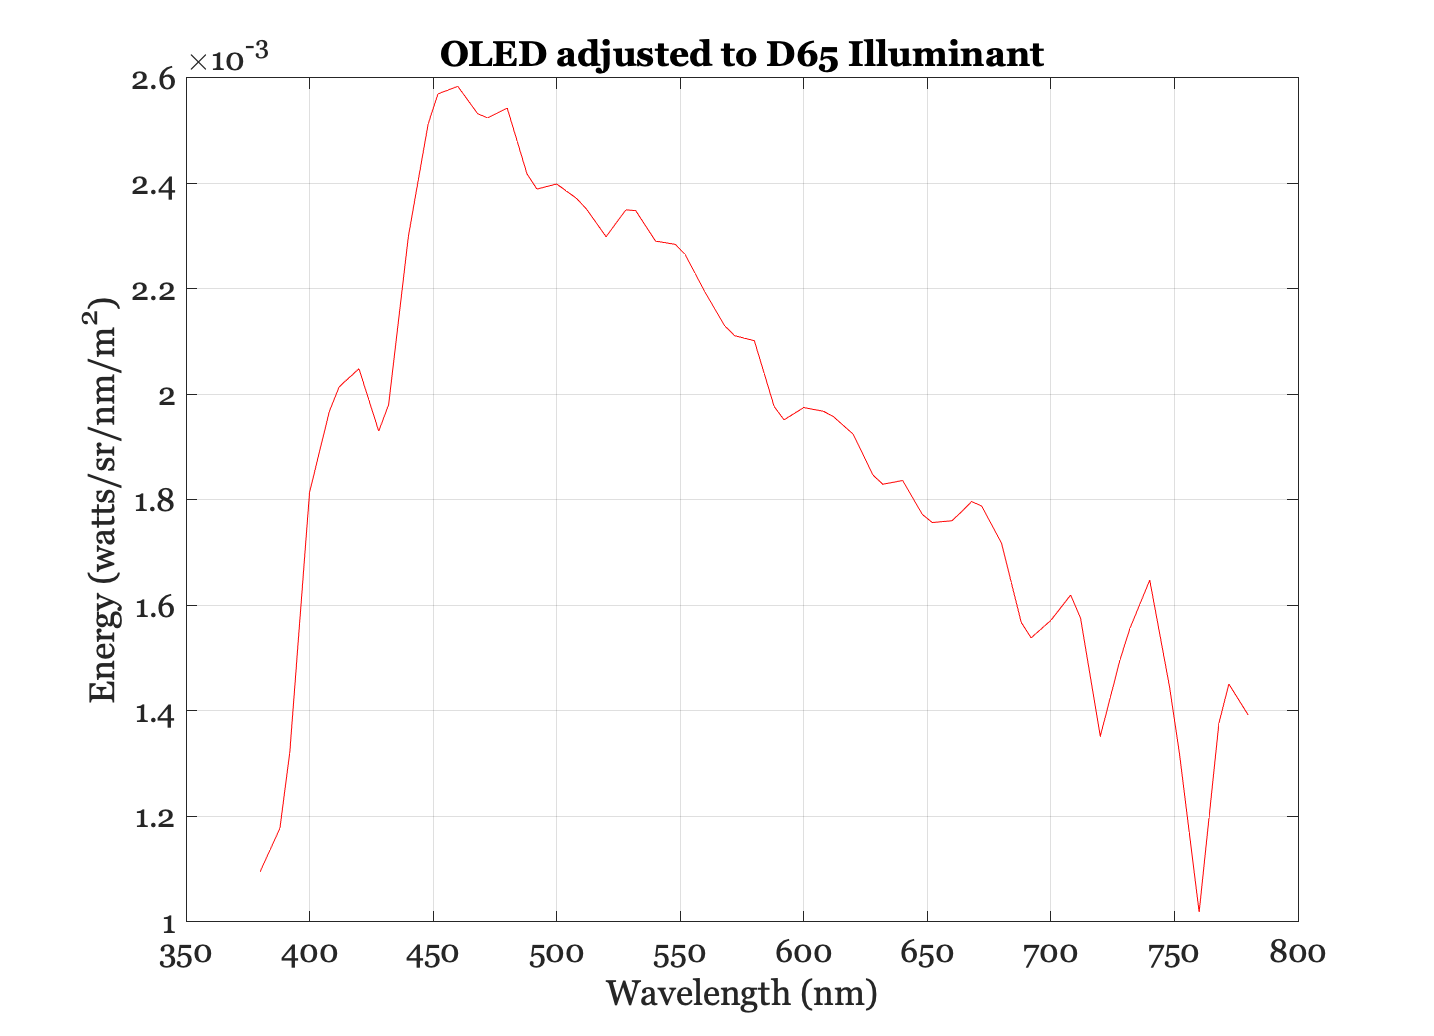

scenePlot(sceneA,'illuminant energy');

The result of this transformation is not only to change the illuminant.  It also changes the implicit surface reflectances, making them more similar to natural reflectances.  

Below we describe a better way to achieve this that is particularly valuable when reading in an RGB image with unknown origin. For comparison, here is the reflectance of the green patch.  This is a pretty unlikely reflectance - though it is consistent with the data.

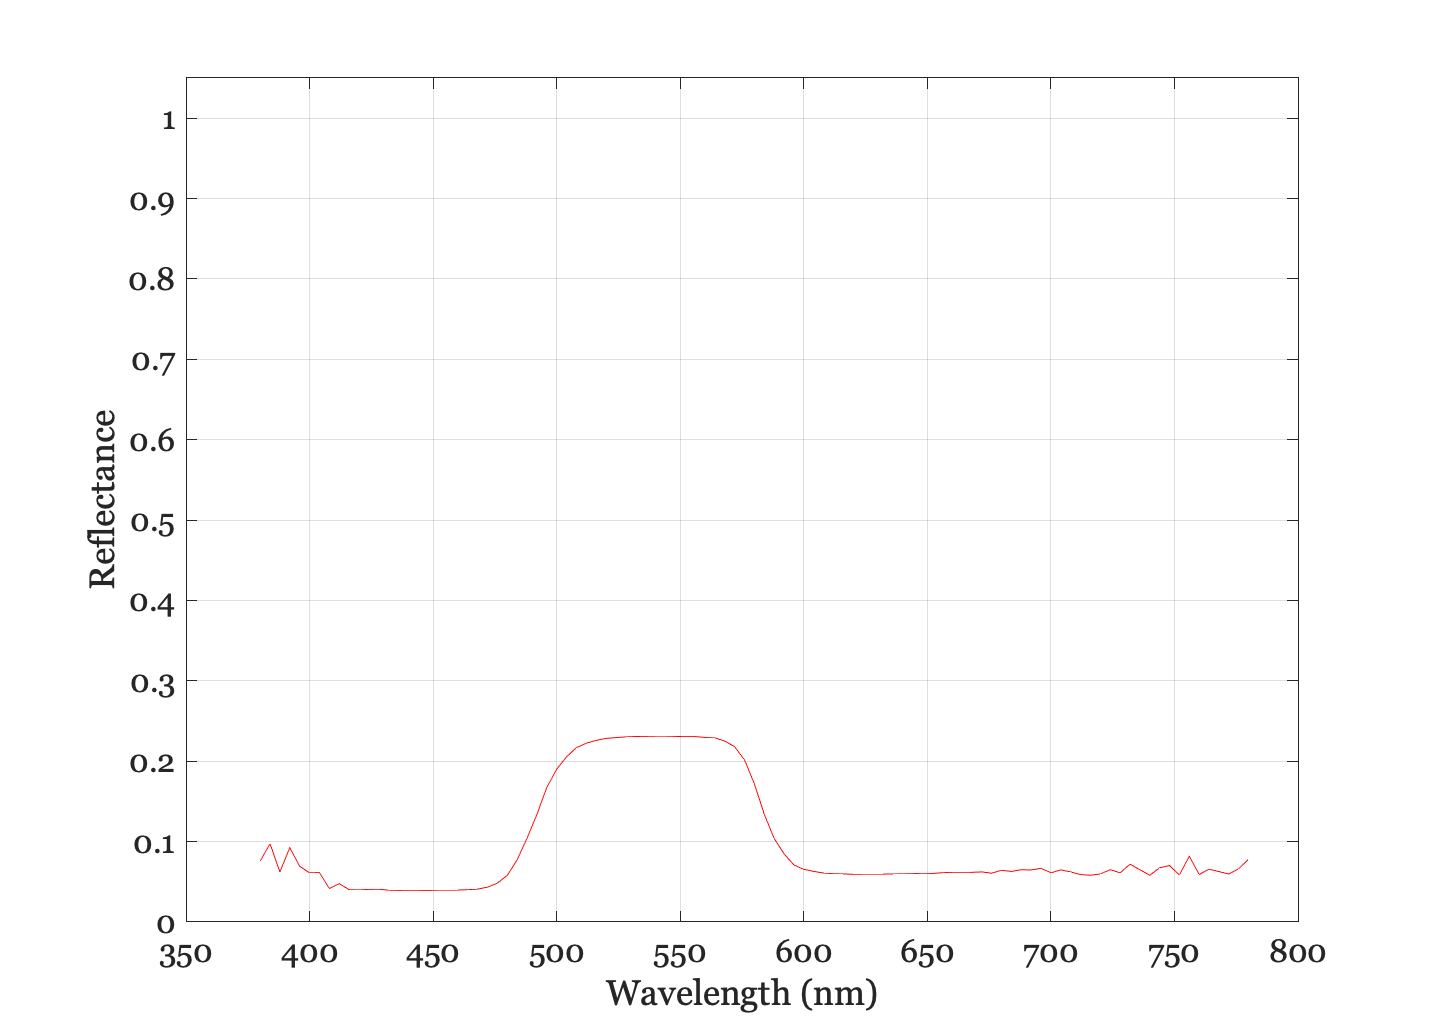

greenRect = [21    34     8    11];
scenePlot(sceneA,'reflectance',greenRect);

## Show scene on LCD

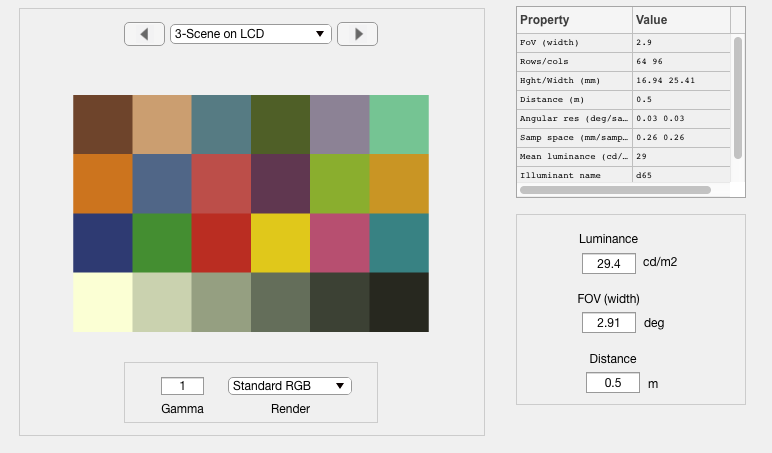

sceneB = sceneFromFile(imgFileName,'rgb',[],dispLCDFile);
sceneB = sceneSet(sceneB,'name','Scene on LCD');
ieAddObject(sceneB); sceneWindow;

## Show scene on CRT

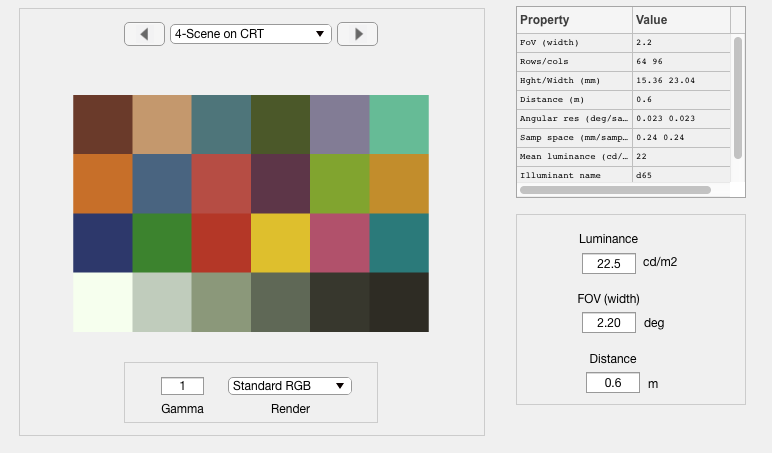

sceneC = sceneFromFile(imgFileName,'rgb',[],dispCRTFile);
sceneC = sceneSet(sceneC,'name','Scene on CRT');
ieAddObject(sceneC); sceneWindow;

## Compare the three images

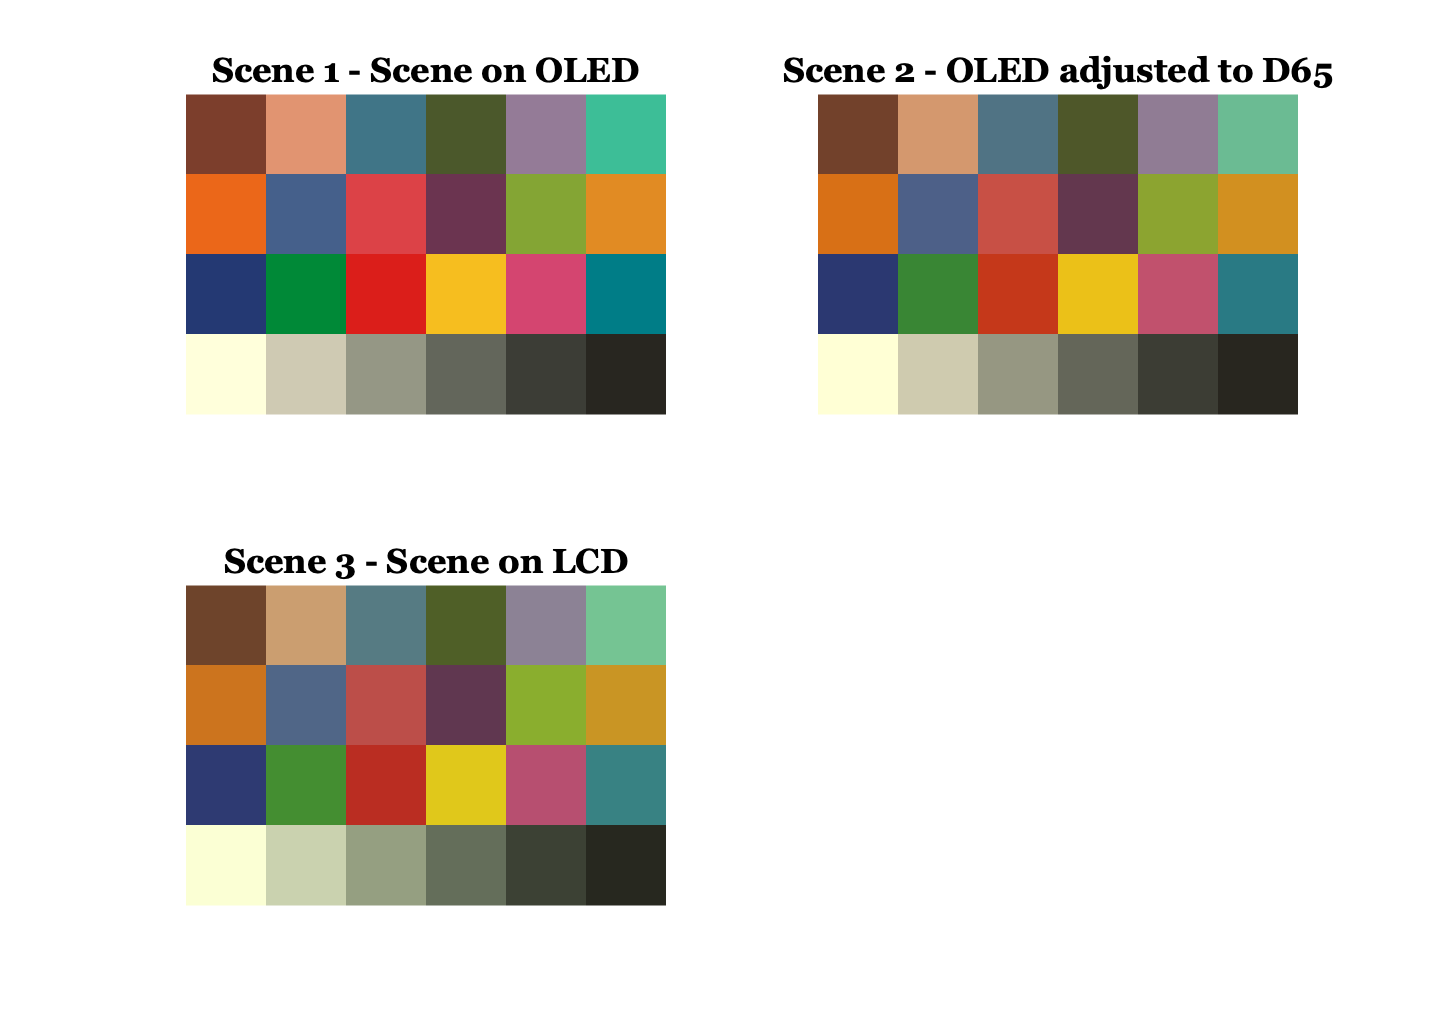

imageMultiview('scene', 1:3, true);

## Compare the  three monitor gamuts

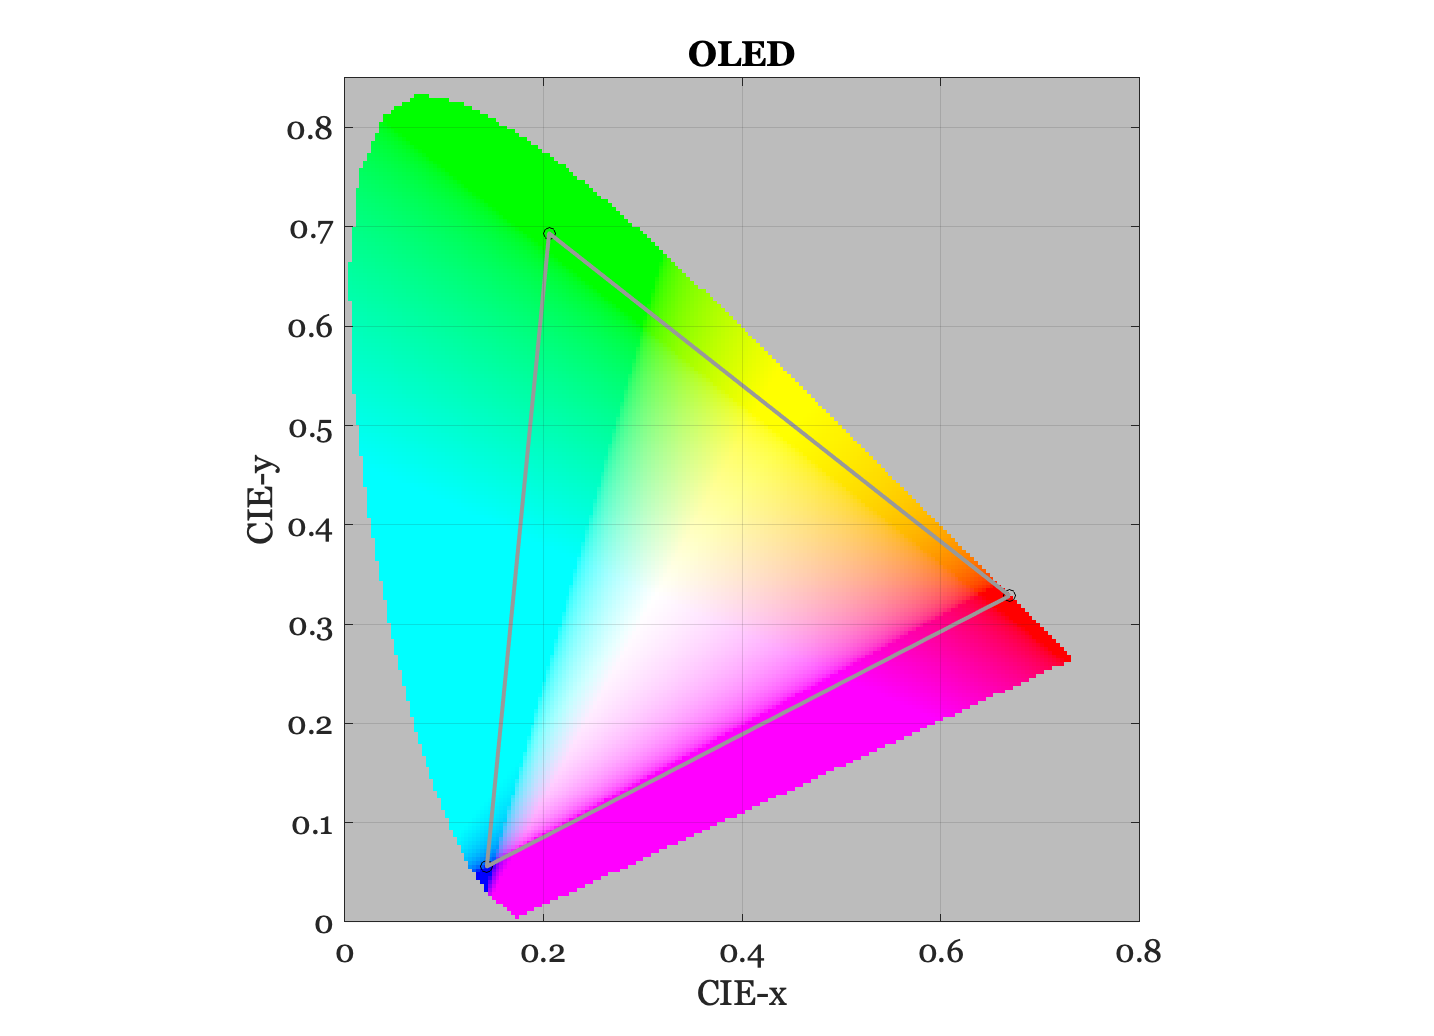

d = displayCreate(dispOLEDFile);
displayPlot(d,'gamut');
title('OLED')

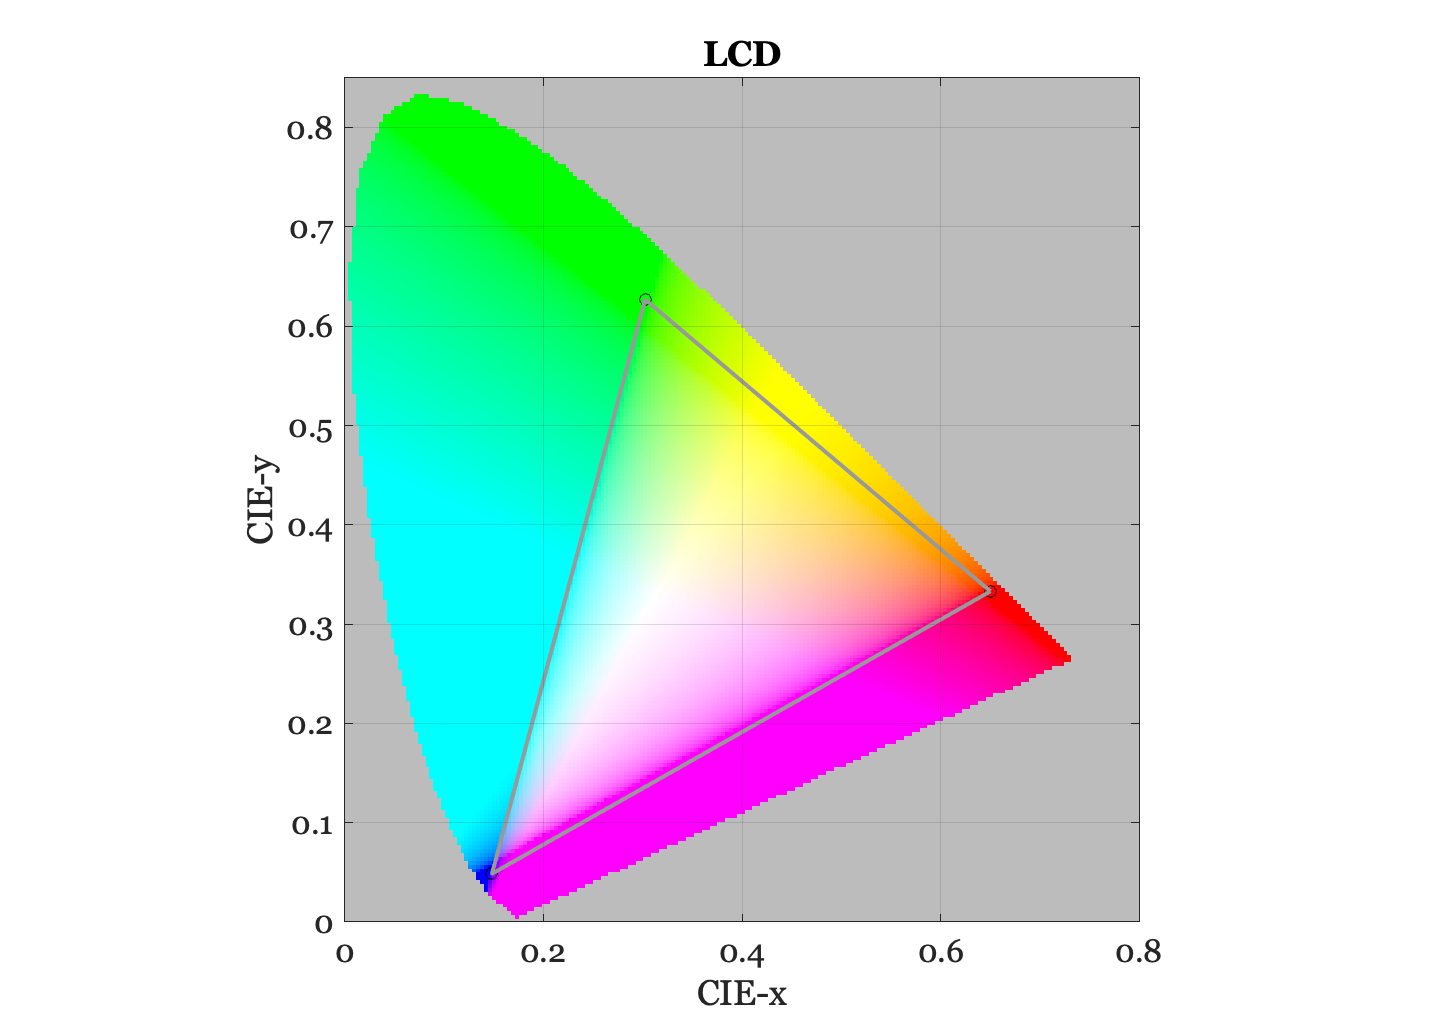


d = displayCreate(dispLCDFile);
displayPlot(d,'gamut');
title('LCD')

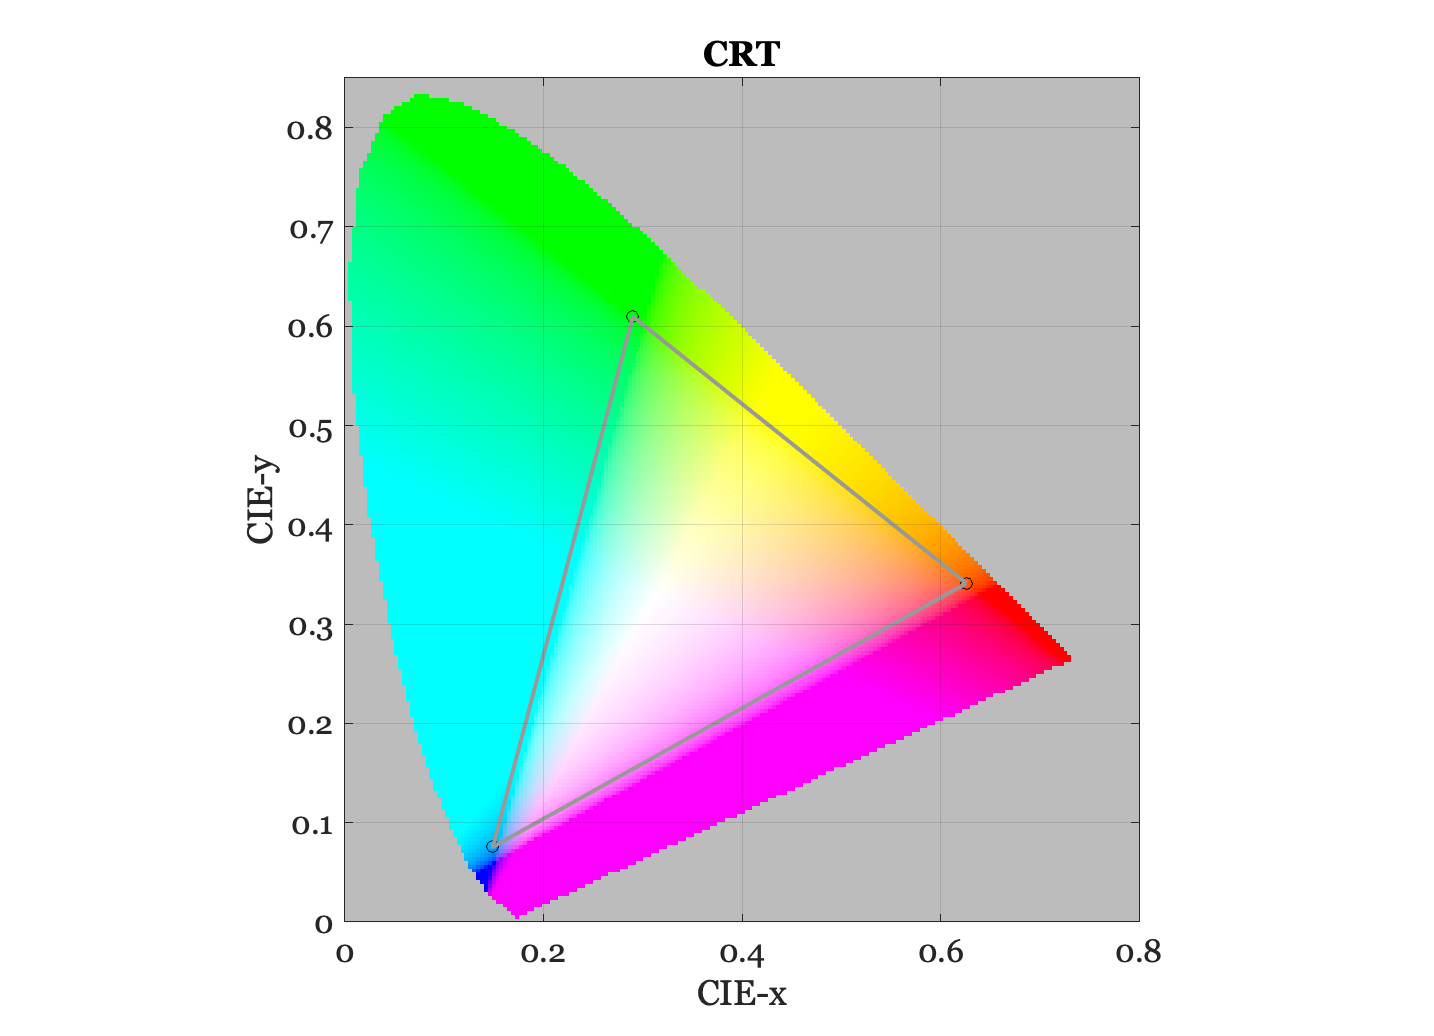


d = displayCreate(dispCRTFile);
displayPlot(d,'gamut');
title('CRT')

## The reflectance-display

For certain cases, we want to convert the RGB image into a plausible light and a set of plausible surface reflectances.  This is the purpose of this special (theoretical) reflectance-display.  The illuminant is D65 and the surface reflectances are consistent with the three basis functions of natural images.

d = displayCreate;

Assigning the spatial dixel from LCD-Apple to the reflectance-display.


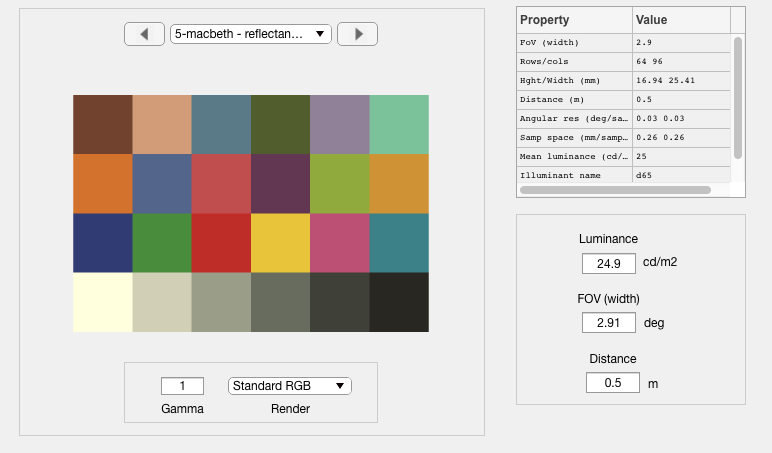

sceneD = sceneFromFile(imgFileName,'rgb',[],d);
ieAddObject(sceneD); sceneWindow;

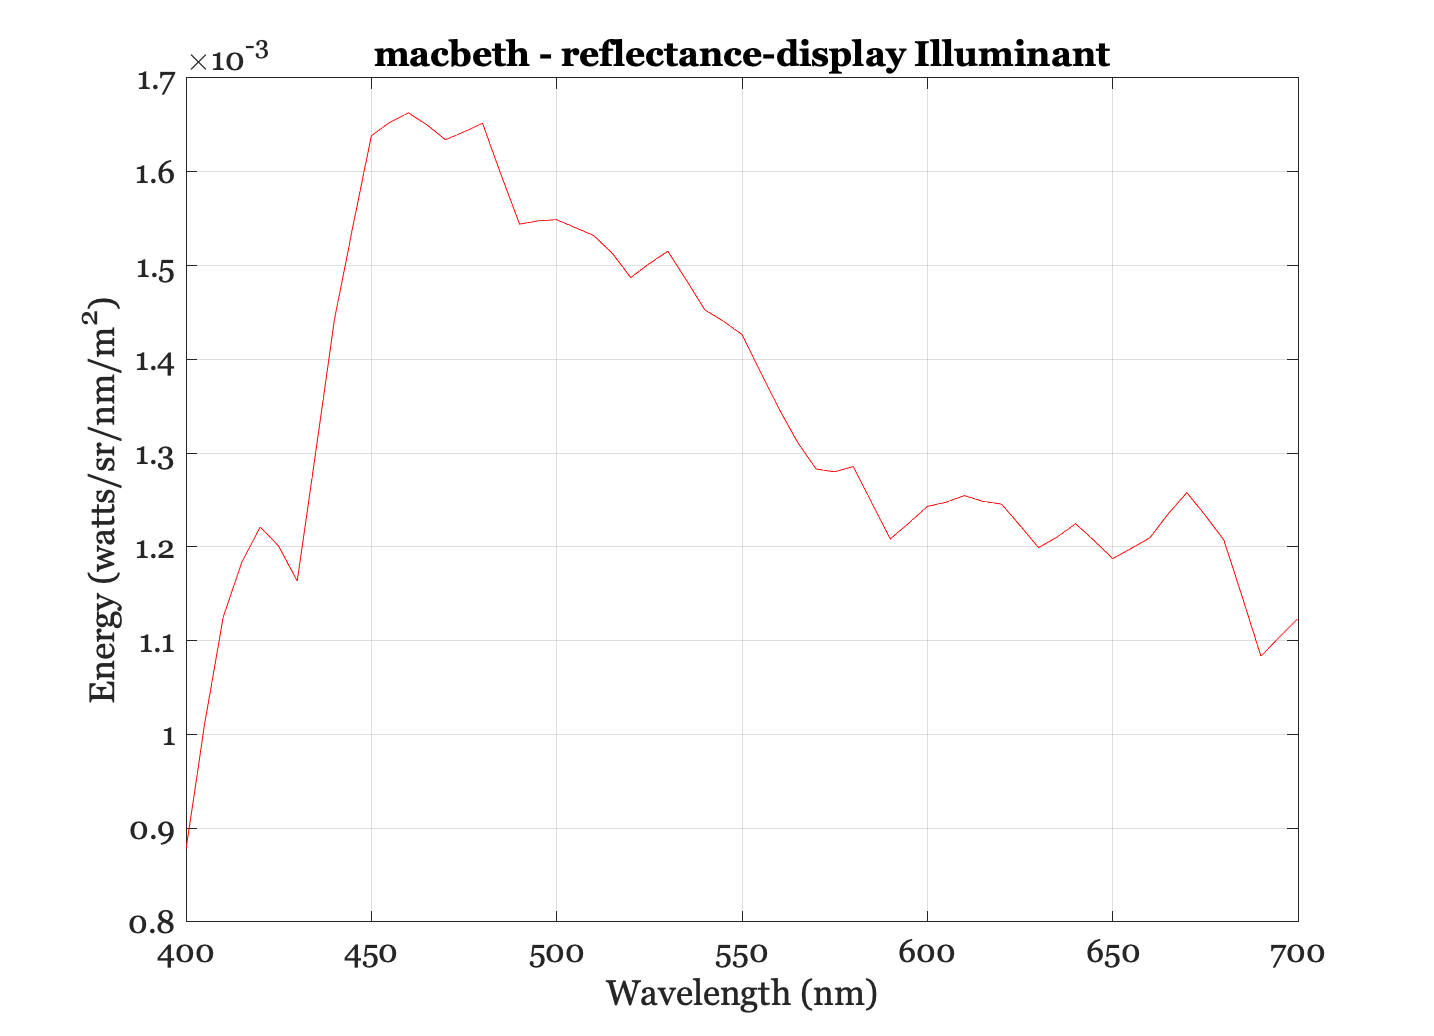

scenePlot(sceneD,'illuminant energy');

Here is the estimate for the green chip surface reflectance, which is consistent with natural surfaces.

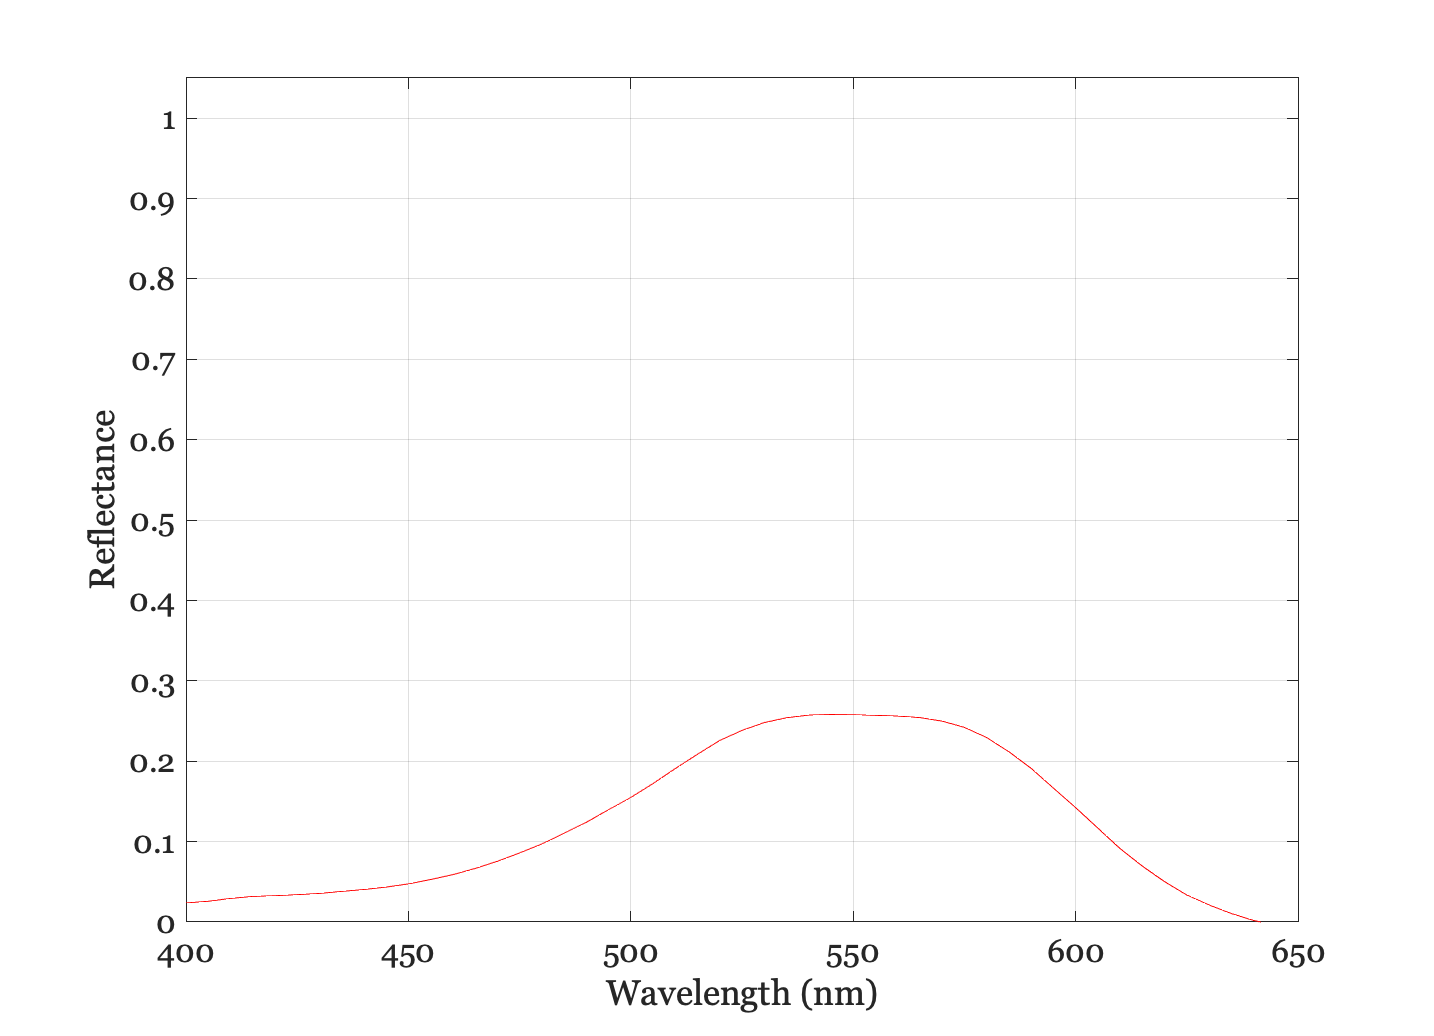

scenePlot(sceneD,'reflectance',greenRect);